% first getting rounded version of x & y coordinate vectors into new
% vector. Using these to index single cells in onsetDf.
RoundXpts = round(abs(ypts)); %switch x & y
RoundYpts = round(abs(xpts));

clear PTSdfof % just in case
for i = 1:length(xpts)
    PTSdfof(i,:,:) = onsetDf(RoundXpts(i),RoundYpts(i),:,:); % 1st x & y point, all frames, all trials/stim presentations
    % note: PTSdfof is points (rows) x frames (columns) x trials (3rd-D)
end
display('size of PTSdfof is: ')
size(PTSdfof)

% now were gonna plot dfof for each point on a different graph, many lines
% because each is a trial over 50 frames (x axis)
frameNum = 1:size(onsetDf,3); % making the x axis frame number - 3rd dimension onf onsetDf 
for i = 1:length(xpts)
    figure
    plot(frameNum,squeeze(PTSdfof(i,:,:))) % grabbing one point at a time, so get rid of single dimension w/squeeze
    ylim([-0.225 0.225]) 
    xlim([0 51])
    hold on 
    % here's plotting the mean over trials (dimension 2 in PTSdfof)
    plot(mean(squeeze(PTSdfof(i,:,:)),2),'linewidth',4)
end

% Like the last code, but plot each graph for each point as subplot 
% on the same main plot

figure % make one figure for all subplots
suptitle(sprintf('dfof vs frames for each pt & mean of all pts'))
for i = 1:length(xpts) % for each point
    subplot(2,3,i)% 
    plot(frameNum,squeeze(PTSdfof(i,:,:))) % plot dfof the first point vs frames for all trials trial
    hold on
    plot(mean(squeeze(PTSdfof(i,:,:)),2),'linewidth',4) 
    ylim([-0.225 0.225]) 
    xlim([0 51])
    
end

hold on % now plot the mean for each point on the 6th subplot
for j = 1:length(xpts)
    subplot(2,3,6)
    plot(mean(squeeze(PTSdfof(j,:,:)),2),'linewidth',1) % here's plotting the mean over trials (dimension 2 in PTSdfof)
    ylim([-0.1 0.1]) 
    xlim([0 51])
    hold on
end

% want the same as last graph, but seperate figures for each contrast

% need to make vectors with contrast values (no flankers yet)
for i=1:length(stimDetails); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    % note: stim details contains info (incl. contrast values) for every 
    % possible condition. It is NOT ordered by trial.
    tc(i) = stimDetails(i).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
end

% note: trial cond is a list of indicies for tc/stimdetails.targContrast.
% These indicies *are* ordered by trial
% so now, by using trialCond to index into tc, we can get a list of target
% contrasts in the order that they were presented:

tcTrial = tc(trialCond); % use trial cond to index into vector of 
% target contrast value for that condition during each trial, save in new
% vector 'tcTrial' that is a list of trial conditions ordered by trial

% we need to get rid of the last trial, because that's what I'm doing now in case there's not 40 frames after onset of last trial
tcTrialMinusOne = tcTrial(1,1:length(trials)-1);

% so now let's make the same subplot as above but 3 seperate figures, one
% for each contrast 
contrasts = unique(tc); % gets a list of the contrast value options, 
% so we know how many contrasts to loop over

for c = 1:length(contrasts)
    figure % need a diff figure for each contrast value
    suptitle(sprintf('contrast = %0.3f', contrasts(c)))
    clear trials
    % note: 'tcTrial' is a list of trial conditions ordered by trial
    % use tcTrialMinusOne to pull trials at this contrast
    trials =  abs(tcTrialMinusOne)==contrasts(c); % for each contrast, create a vector 
    %'trials' that has a zero if that trial has the c-th condtion and a zero
    %if it doesn't (Q: here's were I get confused - how will we use this to
    %index the correct trials?)
    for i = 1:length(xpts) % for each point 
        subplot(2,3,i)% each point gets its own subplot
        set(gcf,'Name',sprintf('tc = %0.3f  n = %d',contrasts(c),sum(trials)));
        % TRIALS-1 is not needed here cuz it's only the trials at this contrast and the last trial was already subtracted earlier
        plot(frameNum,squeeze(PTSdfof(i,:,trials)))% instead of taking all trials, just take the ones indicated by 'trials' vector 
        % Q: again, how, since trials is only 1's and zeros? 
        hold on
        % plotting dfof of each point vs frames but only for the c-th
        % contrast:
        plot(mean(squeeze(PTSdfof(i,:,trials)),2),'linewidth',4) 
        ylim([-0.225 0.225]) 
        xlim([0 51])
    end
    % note: need this next part to be w/in main loop, because we want it on
    % each contrast figure
    
    % now for each contrast figure, I want the 6th subplot to be the
    % mean trace for each point at that contrast
    
    hold on
    for j = 1:length(xpts)
        subplot(2,3,6)
        plot(mean(squeeze(PTSdfof(j,:,trialsMinusOne)),2),'linewidth',1) % here's plotting the mean over trials (dimension 2 in PTSdfof)
        ylim([-0.1 0.1]) 
        xlim([0 51])
        hold on
    end
end

% now we're going to plot one figure, and each subplot is for one point with
% several traces - one for each contrast. Each trace is dfofof for that point, over over frames, for one contrast

figure % only making 1 figure
suptitle(sprintf('dfof of each point vs frames, all contrasts'))   
clear i
for i = 1:length(xpts) % for each point
    subplot(2,3,i) % give each point it's own subplot
    % on each subplot plot the mean dfof across trials, vs frames
    
    % now on each subplot/for each point we're going 
    % to plot the mean across trials at each contrast, for each contrast
    clear c
    for c = 1:length(contrasts) 
        clear trials
        trials =  abs(tcTrialMinusOne)==contrasts(c);
        % conTrialsMinusOne = trials(1,1:length(trials)); % not needed
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,trials),3); % creating a 
        % 1x51 variable that has dfof of one point averaged across trials
        % at the c-th contrast, for all frames
        plot(frameNum,meanOverTrialsPTSdfof)
        ylim([-0.1 0.1]) 
        xlim([0 51])
        hold on
    end 
    % now for each contrast figure, I want the 6th subplot to be the
    % mean trace for each point across all contrasts (this was done in an earlier figure but want it here too)
    hold on
    for j = 1:length(xpts)
        subplot(2,3,6)
        plot(mean(squeeze(PTSdfof(j,:,:)),2),'linewidth',1) % here's plotting the mean over trials (dimension 2 in PTSdfof)
        ylim([-0.05 0.05]) 
        xlim([0 51])
        hold on
        end
end 


%% now we want the Contrast Response Fucntion - subplot of dfof at each point, averaged over time and trials, vs contrast on x axis

% plotting mean
figure 
for i = 1:length(xpts)
    
    clear c 
    for c = 1:length(contrasts)
        clear trials
        trials =  abs(tcTrialMinusOne)==contrasts(c);
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,trials),3);
        meanOverFramesTrialsPTSdfof(c) = mean(meanOverTrialsPTSdfof,2);
    end 
    % 7 contrasts for x axis
    x_axis = [1 2 3 4 5 6 7];
    % size subplot based on 7 contrasts: 0, 0.03, 0.0625, 0.125, 0.25, 0.5, 1
    subplot(2,4,i)
    scatter(x_axis, meanOverFramesTrialsPTSdfof)
    ylim([-0.1 0.1]) 
end 

% same but for max
clear c
clear i
% 7 contrasts for x axis
 x_axis = [1 2 3 4 5 6 7];
figure;
for i = 1:length(xpts)
    clear maxContRespOverFramesTrialsPTSdfof % clear this so the mean dfof for each points dont write over each other, plotting nonsense
    for c = 1:length(contrasts)
        clear trials
        trials =  abs(tcTrialMinusOne)==contrasts(c);
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,trials),3); % take the mean trace across trials, leaving dfof vs frames
        maxOverFramesTrialsPTSdfof = max(meanOverTrialsPTSdfof); % take the max value from that trace
        % save that value each time it's calculated in this loop:
        maxContRespOverFramesTrialsPTSdfof(1,c) = maxOverFramesTrialsPTSdfof;
    end
    % still w/in the points for loop, now that we've collected vector of
    % means for each contrast, plot on subplot for each point
    % size subplot based on 7 contrasts: 0, 0.03, 0.0625, 0.125, 0.25, 0.5, 1
    subplot(2,3,i)
    scatter(x_axis,maxContRespOverFramesTrialsPTSdfof)
    ylim([-0.1 0.1]) 
end

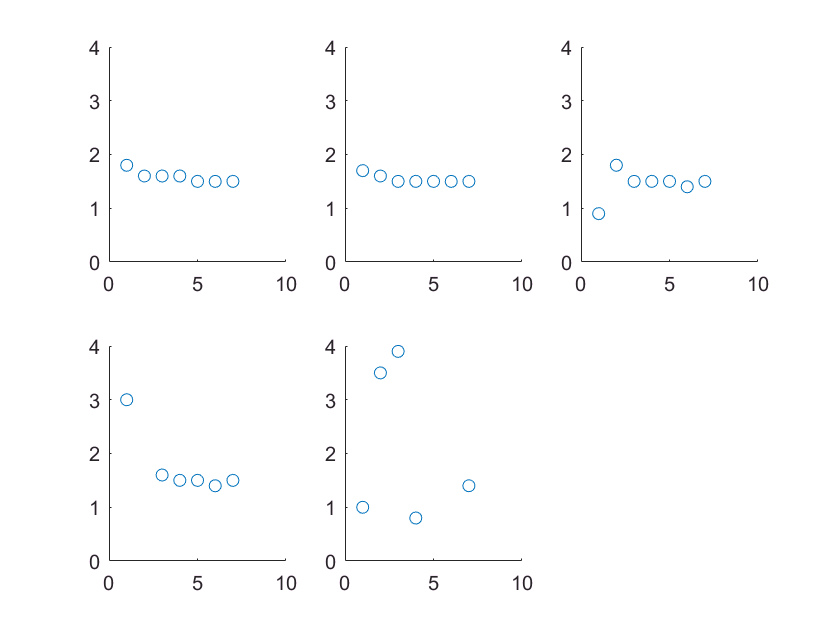

% I'm trying to make graphs like before but plot peak latency vs contrast for each point, not dfof vs contrast
% starts off the same way, set up points loop then contrast loop w/in it
clear c
clear i
% 7 contrasts for x axis
 x_axis = [1 2 3 4 5 6 7];
figure;
for i = 1:length(xpts)
    
    clear maxContRespOverFramesTrialsPTSdfof % clear this so the mean dfof for each points dont write over each other, plotting nonsense
    
    for c = 1:length(contrasts)
        
        clear trials
        clear maxOverFramesTrialsPTSdfof 
        clear latencyInFrames
        clear contLatencyInFrame
        
        trials =  abs(tcTrialMinusOne)==contrasts(c);
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,trials),3); % take the mean trace across trials, leaving dfof vs frames
        maxOverFramesTrialsPTSdfof = max(meanOverTrialsPTSdfof); % take the max value
        % once you have the max value at that contrast, find the frame (column index) it corresponds to
        
        latencyInFrames = find(meanOverTrialsPTSdfof == maxOverFramesTrialsPTSdfof); % LATENCY in imaging frames, assign it to variable
        % One 10 Hz imaging frame = 0.1 second per frame
     
        % collect both latency values into avetors that should be the same length as maxContRespOverFramesTrialsPTSdfof (previous section)
        contLatencyInFrames(1,c) = latencyInFrames; % each column value is the latency at a different contrast 
        % right now we're in frames, we need to be in seconds
        
        
    end 
    
    clear convertFrames2Sec
    % once you have the vector for latencies for one point complete, convert it from frames to secondsfor one point
     format short g
     convertFrames2Sec = 0.1*contLatencyInFrames;
    
    % still w/in the points for loop, now that we've collected vector of
    % latencies for each contrast, plot on subplot for each point
     subplot(2,3,i)
     scatter(x_axis,convertFrames2Sec)
     ylim([0 4.]) 
end 